# ASSIGNMENT 1

# INIT FILE DYNAMIC SIMULATION

clc; close all; clear;

#### Simulation time set-up:

T_sim = 600;              % simulation time [s]
dT = 0.1;                 % time interval [s]
time = 0:dT:T_sim;        % time vector [s]

#### DTU 10 MW data:

rho_air = 1.225;          % air density [kg/m3]
R_rotor = 178.3/2;        % rotor radius [m]
A_rotor = pi*R_rotor^2;   % rotor area [m2]
V_rated = 11.4;           % rated wind speed [m/s]
V_ci = 4;                 % cut-in wind speed [m/s]
V_co = 25;                % cut-out wind speed [m/s]
Jeq = 1.56e8;             % equivalent inertia [kg*m2]
b = 2e5;                  % damping coefficient [N*m*s/rad]
omega_fixed = 0.78;       % fixed rotating speed [rad/s]
n_switch = 0;

#### Cp optimal, Lambda optimal and Rated Torque

lambda_sweep = (2.0:0.1:12.8)';          % tip speed ratio axis from 2.0 to 12.8 []    
% EXPONENTIAL FITTING FORMULA
Cp_curve = PowerFactor(lambda_sweep, 0);
Cp_opt = max(Cp_curve); % Optimal Cp (the highest on the curve)
lambda_opt = lambda_sweep(find(~(Cp_curve - max(Cp_curve)))); %#ok<*FNDSB> % Optimal tip speed ratio
Trated = Cp_opt / lambda_opt * 0.5 * rho_air * A_rotor .* V_rated^2 * R_rotor; % Rated torque

#### Sumulation with RAMP wind profile:

%% SETUP of the wind velocity (min = 0.18, max = 37.71).
Vw_ramp = 0.18 + ((V_co + 12.71)/T_sim) * time;
Vw_in = Vw_ramp;
omega_rotor_0 = Vw_ramp(1)*lambda_opt/R_rotor; % Initial condition (initial rotor speed)

## SIMULATION STALL REGULATED

### Extract Power data from the simulation

Simulink.fileGenControl('set', 'CacheFolder', 'C_Stall Regulated');
Simulink.fileGenControl('set', 'CodeGenFolder', 'C_Stall Regulated');
stallOut = sim('C_Stall Regulated/Stall_regulated_sim.slx');
P_sim_stall = stallOut.P_gen / 1e6;

### STALL Simulated vs Numerical Results

#### Generate the Numerical power curve

V_w = linspace(0.18, 37.71, 100); % Wind velocity has min = 0.18, max = 37.71 [m/s]
P_wind = 1/2 * rho_air * A_rotor * V_w.^3;
lambda_fixed = omega_fixed * R_rotor ./ V_w;
P_num_stall = P_wind .* PowerFactor(lambda_fixed, 0); 
P_num_stall(V_w < 5.5 | V_w > V_co) = 0; % As calculated in the static analisys

#### Plot the comparison between Simulated and Numerical curves

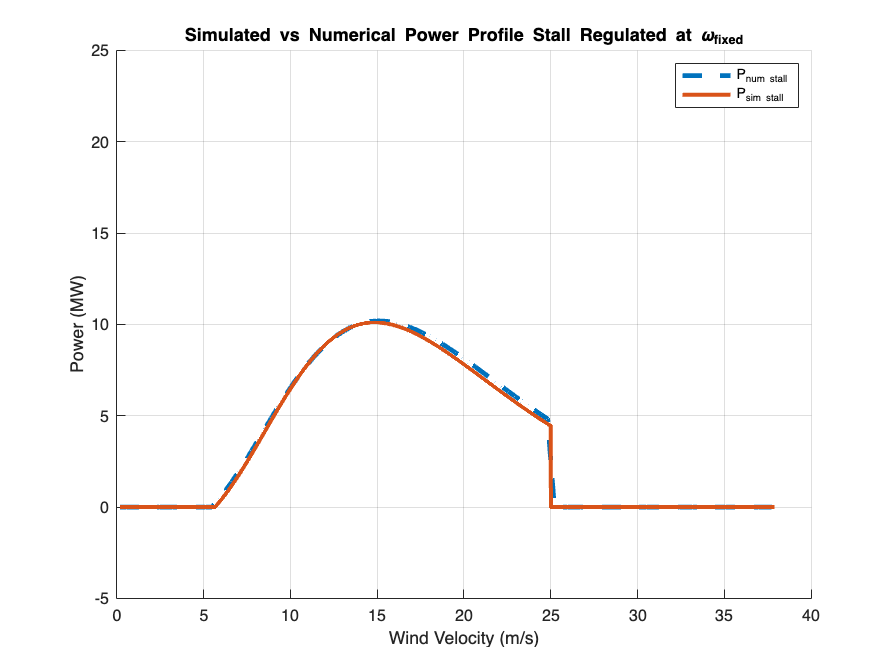

i = 1;
figure(i);
hold on
grid on
% Numerical 
plot(V_w,P_num_stall/1e6,'--','LineWidth',3)
% Simulated
plot(Vw_ramp,P_sim_stall,'LineWidth',2.5)

xlabel('Wind Velocity (m/s)');
ylabel('Power (MW)');
title('Simulated vs Numerical Power Profile Stall Regulated at \omega_{fixed}')
ylim([-5 25])
legend('P_{num stall}', 'P_{sim stall}');
hold off

## SIMULATION PITCH REGULATED

Simulink.fileGenControl('set', 'CacheFolder', 'D_Pitch Regulated');
Simulink.fileGenControl('set', 'CodeGenFolder', 'D_Pitch Regulated');

#### Introducing noise in the wind velocity and set to zero, we will exploit it later

noise = 0 * randn(size(time));
n_switch = 0;

#### SIMULATING

pitchOut = sim('D_Pitch Regulated/Pitch_regulated_sim.slx');
P_sim_pitch = pitchOut.P_gen / 1e6;

### PITCH Simulated vs Numerical Results

#### Numerical power curve

P_wind = 1/2 * rho_air * A_rotor * V_w.^3;
omega_fixed = 0.78; % Taken by the static analisys
lambda_fixed = omega_fixed * R_rotor ./ V_w;

#### Theoretical Power

Prated = 1/2 * rho_air * A_rotor * V_rated^3 * Cp_opt;
% Working Regions 
I1 = find(V_w<V_ci);
I2 = find(V_w>=V_ci & V_w<=V_rated);
I3 = find(V_w>V_rated & V_w<=V_co);
I4 = find(V_w>V_co);

P_num_pitch = 0*V_w;
P_num_pitch(I2) = 0.5*rho_air*V_w(I2).^3*A_rotor*Cp_opt;
P_num_pitch(I3) = Prated; 

#### Plot the comparison between Simulated and Numerical curves

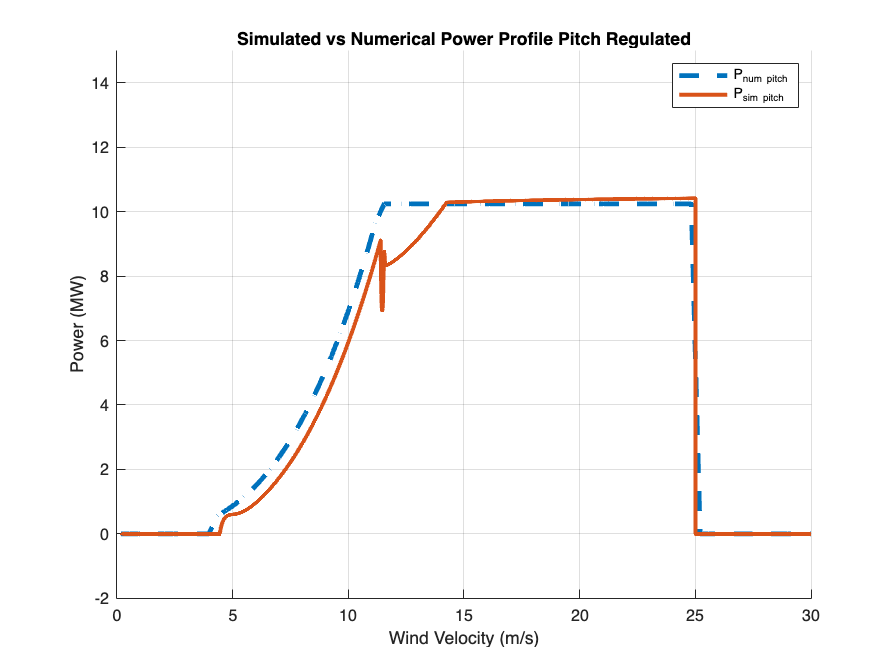

i = i + 1;
figure(i);
hold on
grid on
% Numerical 
plot(V_w,P_num_pitch/1e6,'--','LineWidth',3)
% Simulated
plot(Vw_ramp,P_sim_pitch,'LineWidth',2.5)

xlabel('Wind Velocity (m/s)');
ylabel('Power (MW)');
title('Simulated vs Numerical Power Profile Pitch Regulated')
ylim([-2 15])
xlim([0 30])
legend('P_{num pitch}', 'P_{sim pitch}');
hold off

% Average Power [MW]
pitchAvg = mean(P_sim_pitch)

pitchAvg = 4.2617

## KAIMAL WIND DISTRIBUTION

The wind turbolance intensity is on the order of 10%. The velocities that will be used are the 25th, the 50th, the 75th and the 90th percentile. 

Wind_data = 'Wind_data.csv';
data = readtable(Wind_data, 'VariableNamingRule', 'preserve');
sampled_data = data.("Wind speed (m/s)");

% Wind speed filtering
v_wind = sampled_data(sampled_data >= 0 & isnumeric(sampled_data));

% Significative Velocities
Vw_mean = mean(v_wind);              % Mean velocity of the wind
Vw_25 = quantile(v_wind, 0.25);      % 25° percentile
Vw_50= quantile(v_wind, 0.50);       % 50° percentile (mediana)
Vw_75 = quantile(v_wind, 0.75);      % 75° percentile
Vw_90 = quantile(v_wind, 0.90);      % 90° percentile


### Kaimal Spectrum

Short-term wind speed variations due to turbulence (time-scale below 10 min) can be described using different spectral models,an example being the Kaimal spectrum, described by the following power spectral density: $S\left(f\right) = \frac{I^2V_{10}\,l}{\left(1+1.5\frac{f\,l}{V_{10}}\right)^{5/3}} \:\:\:\:(m^2/s)$.

Considering a finite set of frequencies, a wind speed profile consistent with the PSD is: $v(t) = V_{10} + \sum_{n=1}^N \sqrt{\frac{2S(f_n)}{T}} \cos(2\pi f_nt-\phi_n)$, with $\phi_n$ a set of random numbers in $[0, 2\pi]$.

**Those calculation are included in function Kaimal.m**

% Kaimal Parameters
I = 0.02;                   % Wind intensity (tipically 15%)
L = 600;                    % Characteristic Lenght [m]
N_freq = 100;               % Number of frequencies
f_n = linspace(0.01, 2, N_freq); % Frequencies (0.01 Hz - 2 Hz)
phi_n = 2 * pi * rand(1, N_freq); % Casual phases [rad]

### Mean wind velocity power profile:

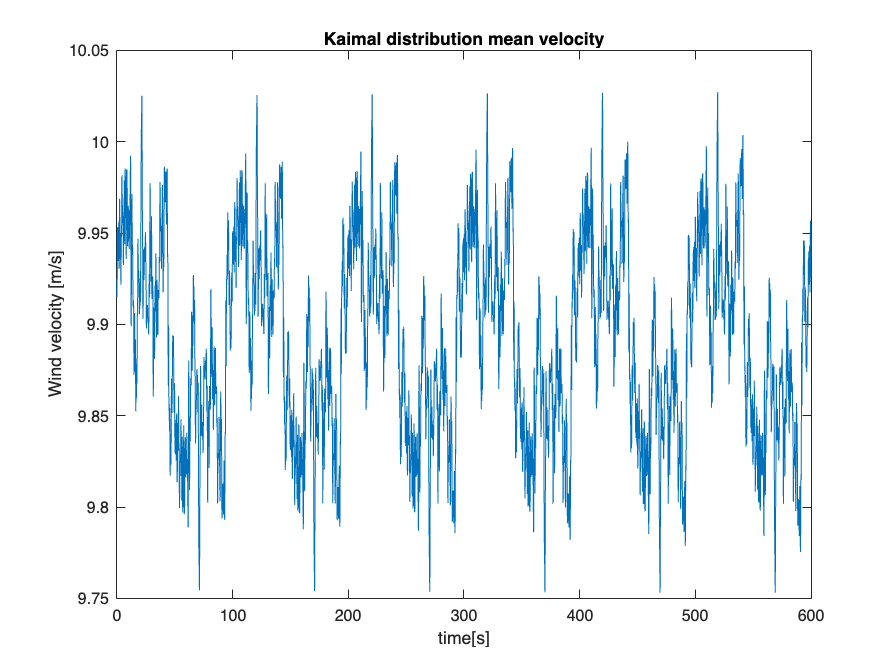

% Velocity signal
Vw_meanK = Kaimal(Vw_mean, I, L, N_freq, f_n, phi_n, time, T_sim);
Vw_in  = Vw_meanK;

i=i+1;
figure(i)
plot(time, Vw_meanK);
xlabel('time[s]');
ylabel('Wind velocity [m/s]');
title('Kaimal distribution mean velocity');

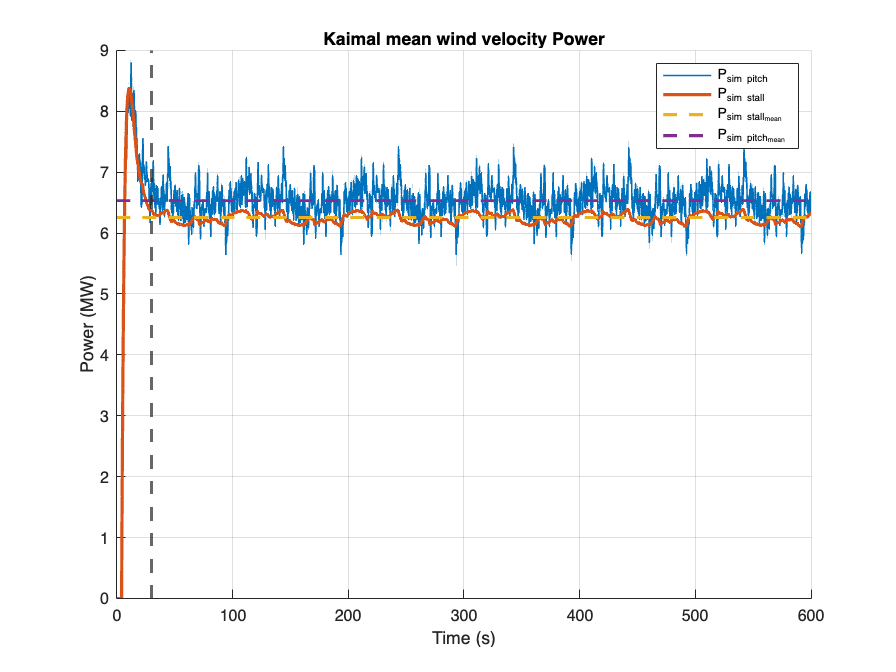

% Stall Power Mean
stallOut= sim('C_Stall Regulated/Stall_regulated_sim.slx');
P_sim_stall_meanK = stallOut.P_gen / 1e6;

% Pitch Power Mean
pitchOut= sim('D_Pitch Regulated/Pitch_regulated_sim.slx');
P_sim_pitch_meanK = pitchOut.P_gen / 1e6;

% Mean Values Mean
P_mean_stall_meanK = mean(P_sim_stall_meanK(31:end)); % Before t = 31 we have dirty values
P_mean_pitch_meanK = mean(P_sim_pitch_meanK(31:end)); % Before t = 31 we have dirty values

i = i + 1;
figure(i);
hold on
grid on
plot(time, P_sim_pitch_meanK, 'LineWidth', 1)
plot(time, P_sim_stall_meanK, 'LineWidth', 2)
plot(time, ones(size(time)) * P_mean_stall_meanK, '--', 'LineWidth', 2)
plot(time, ones(size(time)) * P_mean_pitch_meanK, '--', 'LineWidth', 2)
xline(30, '--', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Power (MW)');
title('Kaimal mean wind velocity Power')
legend('P_{sim pitch}','P_{sim stall}','P_{sim stall_{mean}}','P_{sim pitch_{mean}}');
hold off

% Percentage ratio:
fprintf("With a wind velocity corresponding to the perturbed mean velocity, the ratio between Pitch and Stall power is: %.2f %%", P_mean_pitch_meanK/P_mean_stall_meanK*100);

With a wind velocity corresponding to the perturbed mean velocity, the ratio between Pitch and Stall power is: 104.32 %

### 25th Percentile wind velocity power profile.

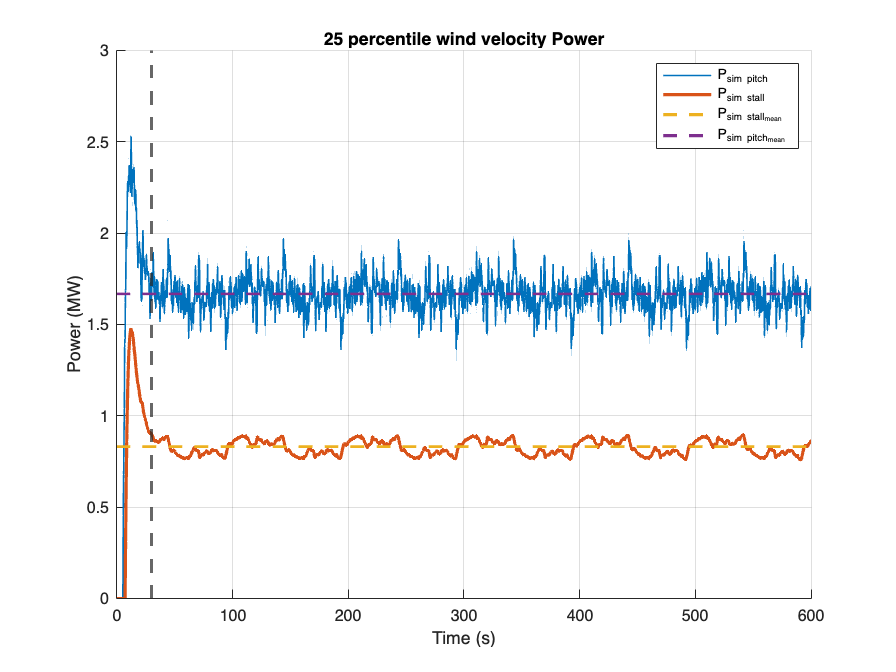

% Velocity signal
Vw_t_25 = Kaimal(Vw_25, I, L, N_freq, f_n, phi_n, time, T_sim);
Vw_in  = Vw_t_25;

% Stall Power 25
stallOut= sim('C_Stall Regulated/Stall_regulated_sim.slx');
P_sim_stall_25 = stallOut.P_gen / 1e6;

% Pitch Power 25
pitchOut= sim('D_Pitch Regulated/Pitch_regulated_sim.slx');
P_sim_pitch_25= pitchOut.P_gen / 1e6;

% Mean Values 25
P_mean_stall_25 = mean(P_sim_stall_25(31:end));
P_mean_pitch_25 = mean(P_sim_pitch_25(31:end));

i = i + 1;
figure(i);
hold on
grid on
plot(time, P_sim_pitch_25, 'LineWidth', 1)
plot(time, P_sim_stall_25, 'LineWidth', 2)
plot(time, ones(size(time)) * P_mean_stall_25, '--', 'LineWidth', 2)
plot(time, ones(size(time)) * P_mean_pitch_25, '--', 'LineWidth', 2)
xline(30, '--', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Power (MW)');
title('25 percentile wind velocity Power')
legend('P_{sim pitch}','P_{sim stall}','P_{sim stall_{mean}}','P_{sim pitch_{mean}}');
hold off

% Percentage ratio:
fprintf("With a wind velocity corresponding to the perturbed 25th percentile velocity, the ratio between Pitch and Stall power is: %.2f %%", P_mean_pitch_25/P_mean_stall_25*100);

With a wind velocity corresponding to the perturbed 25th percentile velocity, the ratio between Pitch and Stall power is: 200.73 %

### 50th Percentile wind velocity power profile

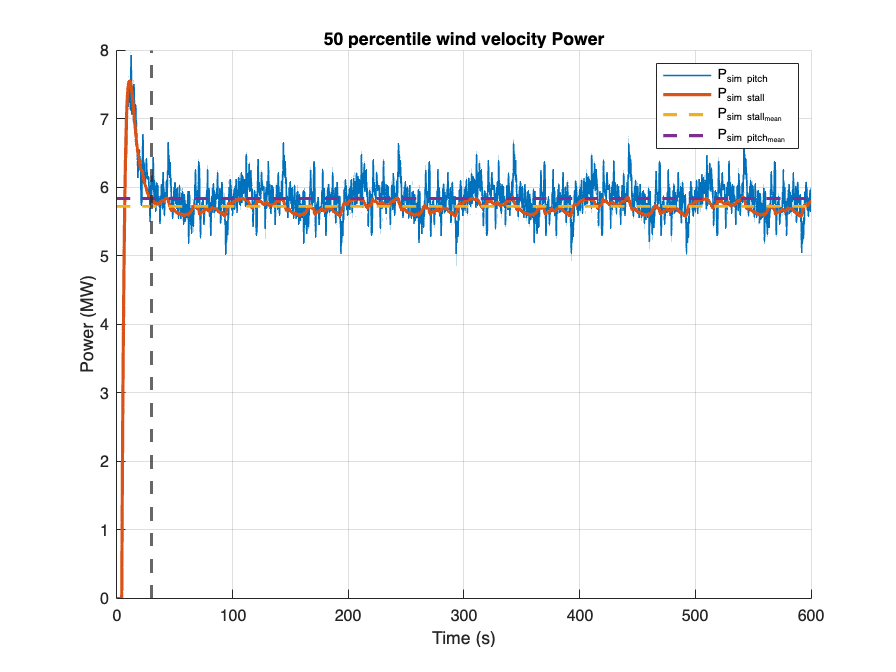

% Velocity signal
Vw_t_50 = Kaimal(Vw_50, I, L, N_freq, f_n, phi_n, time, T_sim);
Vw_in  = Vw_t_50;

% Stall Power 50
stallOut= sim('C_Stall Regulated/Stall_regulated_sim.slx');
P_sim_stall_50 = stallOut.P_gen / 1e6;

% Pitch Power 50
pitchOut = sim('D_Pitch Regulated/Pitch_regulated_sim.slx');
P_sim_pitch_50 = pitchOut.P_gen / 1e6;

% Mean Values 50
P_mean_stall_50 = mean(P_sim_stall_50(31:end));
P_mean_pitch_50 = mean(P_sim_pitch_50(31:end));

i = i + 1;
figure(i);
hold on
grid on
plot(time, P_sim_pitch_50, 'LineWidth', 1)
plot(time, P_sim_stall_50, 'LineWidth', 2)
plot(time, ones(size(time)) * P_mean_stall_50, '--', 'LineWidth', 2)
plot(time, ones(size(time)) * P_mean_pitch_50, '--', 'LineWidth', 2)
xline(30, '--', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Power (MW)');
title('50 percentile wind velocity Power')
legend('P_{sim pitch}','P_{sim stall}','P_{sim stall_{mean}}','P_{sim pitch_{mean}}');
hold off

% Percentage ratio:
fprintf("With a wind velocity corresponding to the perturbed 50th percentile velocity, the ratio between Pitch and Stall power is: %.2f %%", P_mean_pitch_50/P_mean_stall_50*100);

With a wind velocity corresponding to the perturbed 50th percentile velocity, the ratio between Pitch and Stall power is: 101.94 %

### 90th Percentile wind velocity power profile

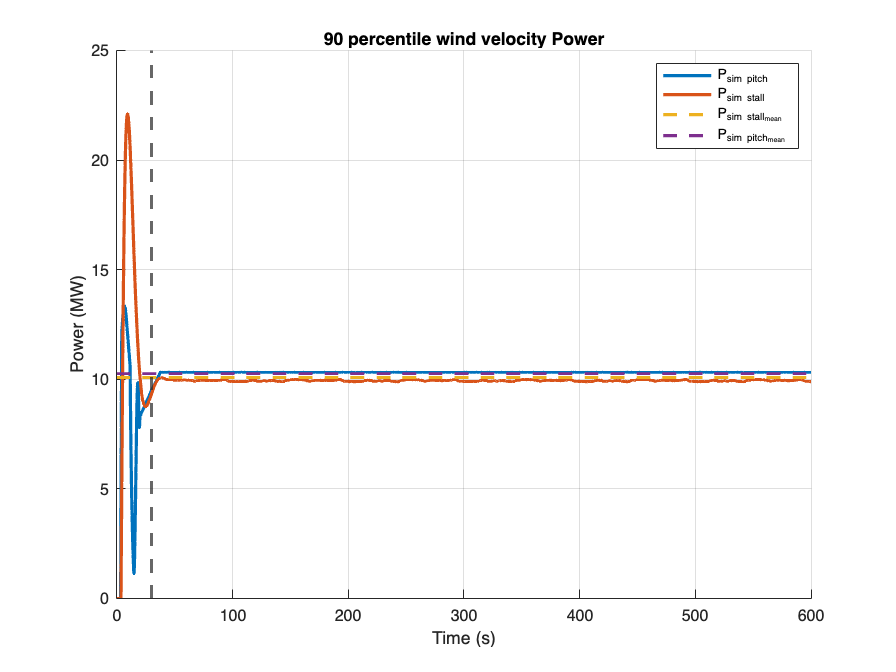

% Velocity signal
Vw_t_90 = Kaimal(Vw_90, I, L, N_freq, f_n, phi_n, time, T_sim);
Vw_in  = Vw_t_90;

% Stall Power 90
stallOut = sim('C_Stall Regulated/Stall_regulated_sim.slx');
P_sim_stall_90 = stallOut.P_gen / 1e6;

% Pitch Power 90
pitchOut = sim('D_Pitch Regulated/Pitch_regulated_sim.slx');
P_sim_pitch_90 = pitchOut.P_gen / 1e6;

% Mean Values 90
P_mean_stall_90 = mean(P_sim_stall_90(31:end));
P_mean_pitch_90 = mean(P_sim_pitch_90(31:end));

i = i + 1;
figure(i);
hold on
grid on
plot(time, P_sim_pitch_90, 'LineWidth', 2)
plot(time, P_sim_stall_90, 'LineWidth', 2)
plot(time, ones(size(time)) * P_mean_stall_90, '--', 'LineWidth', 2)
plot(time, ones(size(time)) * P_mean_pitch_90, '--', 'LineWidth', 2)
xline(30, '--', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Power (MW)');
title('90 percentile wind velocity Power')
legend('P_{sim pitch}','P_{sim stall}','P_{sim stall_{mean}}','P_{sim pitch_{mean}}');
hold off

% Percentage ratio:
fprintf("With a wind velocity corresponding to the perturbed 90th percentile velocity, the ratio between Pitch and Stall power is: %.2f %%", P_mean_pitch_90/P_mean_stall_90*100);

With a wind velocity corresponding to the perturbed 90th percentile velocity, the ratio between Pitch and Stall power is: 101.71 %

display(P_mean_pitch_90/P_mean_stall_90*100);

  101.7115



## NOISE INTRODUCTION ON THE ANEMOMETER

Assume that the anemometer of the pitch control system is affected by a noise. The noise introduces a standard deviation of 0.5.

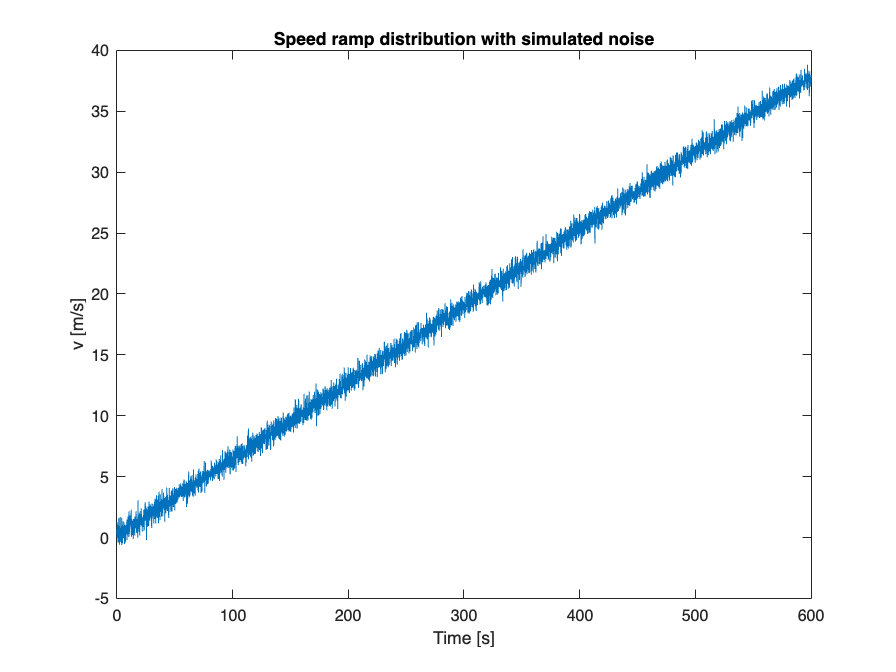

n_switch = 1;
% Adding noise similar to that of an anemometer
noise_std = 0.5;           % Standard deviation of noise [m/s]
noise = noise_std * randn(size(time));  % Random noise

% Visualize noisy velocity ramp
Vw_noisy = Vw_ramp + noise; 
i=i+1;
plot(time, Vw_noisy);
xlabel('Time [s]');
ylabel('v [m/s]');
title('Speed ramp distribution with simulated noise');

% Real wind speed entering the Turbine
Vw_in = Vw_ramp;

Sim_noise = sim('D_Pitch Regulated/Pitch_regulated_sim.slx');
pitchOut_noise = Sim_noise.P_gen;
pitchAvg_noise = mean(pitchOut_noise);
noise_efficiency = (pitchAvg_noise / pitchAvg)/1e6

noise_efficiency = 0.9949

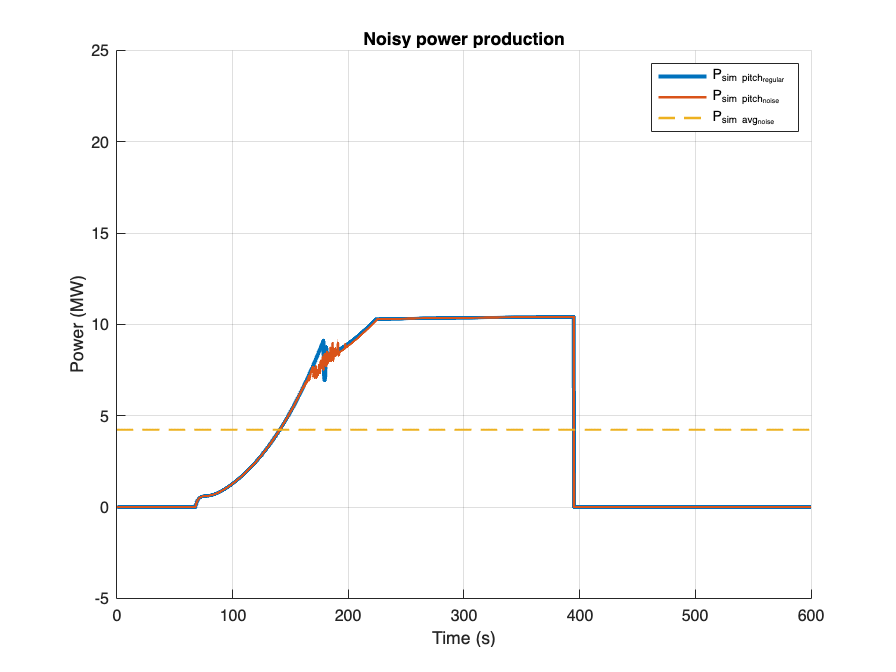

i = i + 1;
figure(i);
hold on
grid on
plot(time, P_sim_pitch, 'LineWidth', 2.5)
plot(time, (pitchOut_noise)/1e6, 'LineWidth', 1.5)
plot(time, (ones(size(time)) * pitchAvg_noise)/1e6, '--', 'LineWidth', 1.5)
ylim([-5 25])
xlabel('Time (s)');
ylabel('Power (MW)');
title('Noisy power production')
legend('P_{sim pitch_{regular}}', 'P_{sim pitch_{noise}}', 'P_{sim avg_{noise}}');
hold off